# DSZOB, cvičenie 2.

## **Zadanie:**

## **Úloha 1 – Základné generovanie signálov**

Vygenerujte a vhodne vizualizujte nasledovné signály (vzorkovacia frekvencia 44.1 kHz, časový úsek 3 sekundy):

- Sínusový signál s frekvenciou zvoleného tónu temperovaného ladenia (vid tab. dole) a magnitúdou = 0,7.

- Sínusový signál s frekvenciou iného zvoleného tónu temperovaného ladenia (vid tab. dole) a magnitúdou z rozsahu <0,2:0,5>.

- Sínusový signál s frekvenciou iného zvoleného tónu temperovaného ladenia (vid tab. dole) a magnitúdou z rozsahu  <0,1:0,4>.

- Generujte zložený signál ako súčet  z predchádzajúcich vygenerovaných signálov. 

- K zloženému signálu aditívne pripočítajte šum s magnitúdou z rozsahu <0,01:0,05>.

(pomôcka: funkcia *rand()* alebo  *randn() )*

Vygenerované signály si vypočujte po sebe v poradí generovania (zložený signál na záver).

Vygenerované signály vizualizujte!

Pozn.: Môžete sa pokúsit o akord (vid tab. dole)

## **Tab. Temperované ladenie - frekvencie**

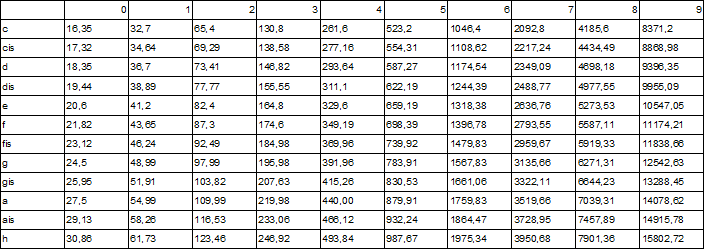

**Príklady akordov / Tóny, z ktorých sa skladá:**

- Cdur / **C, E, G**

- Gdur / **G, H, D**

- Amoll / **A, C, E**

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

fs = 44100;
sx = 0:1/fs:3;
sy1 = 0.7*sin(2*pi*sx*4185.6);
sy2 = 0.15*sin(2*pi*sx*3135.66)+.35;
sy3 = 0.15*sin(2*pi*sx*1479.83)+.25;
sy4 = sy1 + sy2 + sy3;
sy5 = sy4 + rand(1, 44100*3 + 1)*0.04 + 0.01;

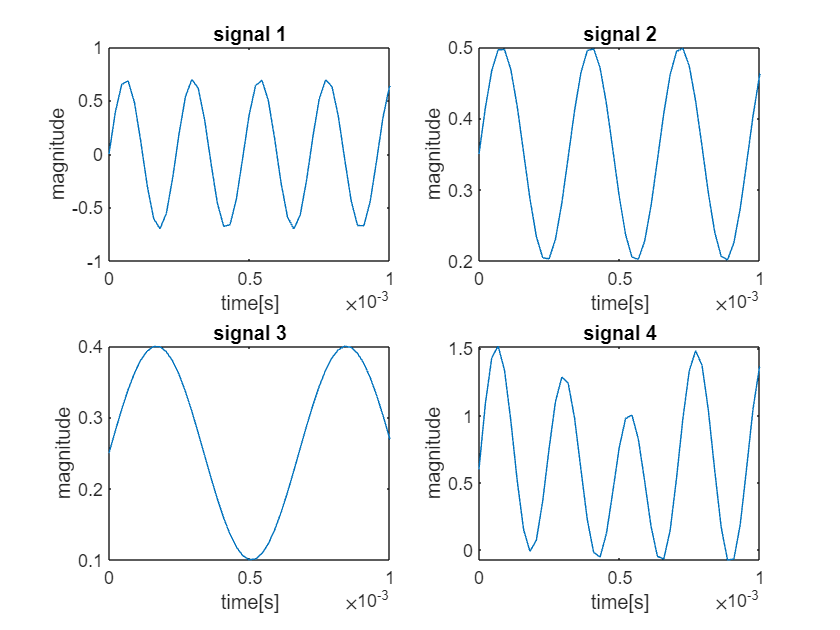

figure;
subplot(2,2,1)
plot(sx, sy1)
xlim([0 0.001])
title("signal 1")
xlabel("time[s]")
ylabel("magnitude")
subplot(2,2,2)
plot(sx, sy2)
xlim([0 0.001])
title("signal 2")
xlabel("time[s]")
ylabel("magnitude")
subplot(2,2,3)
plot(sx, sy3)
xlim([0 0.001])
title("signal 3")
xlabel("time[s]")
ylabel("magnitude")
subplot(2,2,4)
plot(sx, sy4)
xlim([0 0.001])
title("signal 4")
xlabel("time[s]")
ylabel("magnitude")

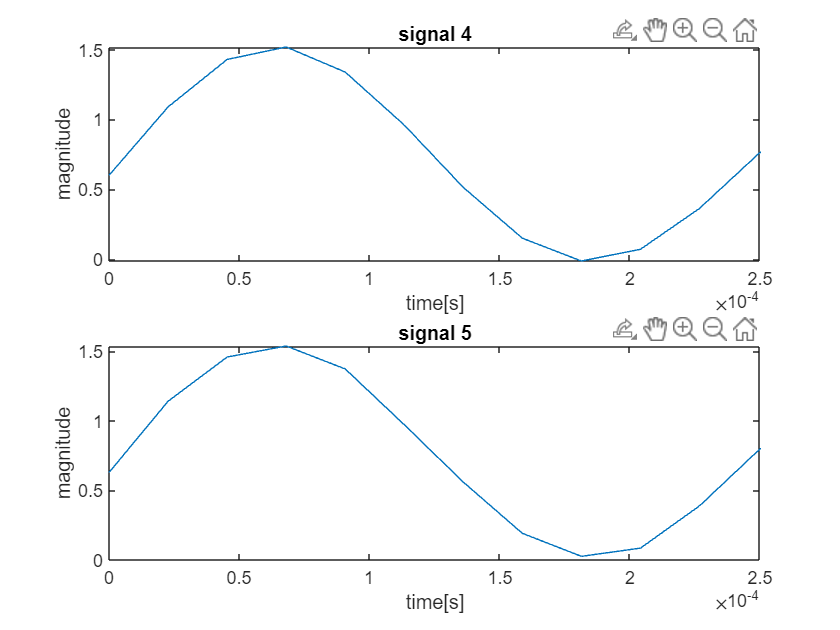

figure;
subplot(2,1,1)
plot(sx, sy4)
xlim([0 0.00025])
title("signal 4")
xlabel("time[s]")
ylabel("magnitude")
subplot(2,1,2)
plot(sx, sy5)
xlim([0 0.00025])
title("signal 5")
xlabel("time[s]")
ylabel("magnitude")

Pridaním šumu k signálu vidíme rozdiely. Tento pri pôvodne zvolených frekvenciách nie je až tak hmatateľný, ale posun je pozorovateľný napríklad medzi 15 a 20 ms.

% sound(sy1, fs)
% sound(sy2, fs)
% sound(sy3, fs)
% sound(sy4, fs)
% sound(sy5, fs)

## **Úloha 2**

Znížte vzorkovaciu frekvenciu u Vami vygenerovaného signálu:

- na polovicu

- na štvrtinu

- na hranicu danú Nyquistovým  teorémom

- a aj s porušením Nyquistovho  teorému. 

Vizualizujte dané signály v jednom grafe. Signál si vypočujte a vyhodnoťte kvalitu.

Pomôcky : funkcia: *downsample()*

sy_2 = downsample(sy5, 2);
sx_2 = downsample(sx, 2);

sy_4 = downsample(sy5, 4);
sx_4 = downsample(sx, 4);

sy_nyq_gt = downsample(sy5, 5);
sx_nyq_gt = downsample(sx, 5);

sy_nyq_lt = downsample(sy5, 6);
sx_nyq_lt = downsample(sx, 6);

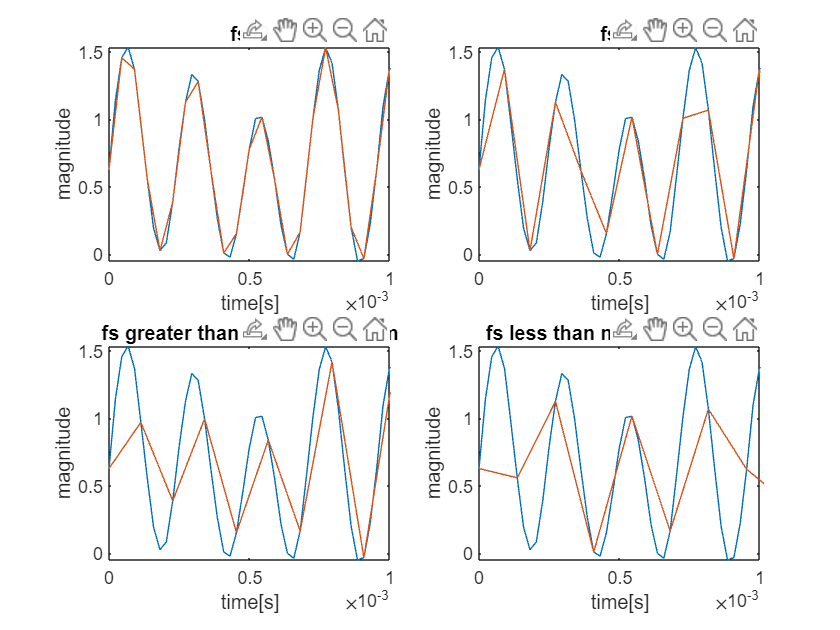

figure;
subplot(2,2,1)
plot(sx, sy5, sx_2, sy_2)
xlim([0 0.001])
title("fs /2")
xlabel("time[s]")
ylabel("magnitude")
subplot(2,2,2)
plot(sx, sy5, sx_4, sy_4)
xlim([0 0.001])
title("fs /4")
xlabel("time[s]")
ylabel("magnitude")
subplot(2,2,3)
plot(sx, sy5, sx_nyq_gt, sy_nyq_gt)
xlim([0 0.001])
title("fs greater than nyquist theorem")
xlabel("time[s]")
ylabel("magnitude")
subplot(2,2,4)
plot(sx, sy5, sx_nyq_lt, sy_nyq_lt)
xlim([0 0.001])
title("fs less than nyquist theorem")
xlabel("time[s]")
ylabel("magnitude")

Postupným znižovaním vzorkovacej frekvencie dostávame signál ktorý menej a menej zodpovedá pôvodnému, ale kým dodržíme nyquistov teorém signál stále aspoň približne kopíruje tvar pôvodného signálu a dobrou aproximáciou krivky signálu je ho možné zreprodukovať. Porušením nyquistovho teorému dostávame signál, ktorý vôbec nemusí zodpovedať pôvodnému a teda pôvodný signál nie je možné zreprodukovať.

% sound(sy_2, fs/2)
% sound(sy_4, fs/4)
% sound(sy_nyq_gt, fs/5)
% sound(sy_nyq_lt, fs/6)